# Figure 3B, 3C, 3E

**Load Data**

clear
[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = '..\..\FINAL DATA files';

load([dataDir filesep 'F021_data.mat'],'S','settings','allIF');
conditions = settings.conditions

conditions = 20×6 cell array
    {'siCtrl NR75 DMSO/DMSO'}    {[1 2 3 4]}    {[ 2]}    {[1]}    {[0 0 0]}    {[0 10]}
    {'siFZR1 NR75 DMSO/DMSO'}    {[1 2 3 4]}    {[ 3]}    {[1]}    {[0 0 0]}    {[0 10]}
    {'siCtrl NR75 DMSO/DOX' }    {[1 2 3 4]}    {[ 4]}    {[1]}    {[0 0 0]}    {[0 10]}
    {'siFZR1 NR75 DMSO/DOX' }    {[1 2 3 4]}    {[ 5]}    {[1]}    {[0 0 0]}    {[0 10]}
    {'siCtrl NR75 46i/DMSO' }    {[1 2 3 4]}    {[ 6]}    {[1]}    {[0 0 0]}    {[0 10]}
    {'siFZR1 NR75 46i/DMSO' }    {[1 2 3 4]}    {[ 7]}    {[1]}    {[0 0 0]}    {[0 10]}
    {'siCtrl NR75 46i/DOX'  }    {[1 2 3 4]}    {[ 8]}    {[1]}    {[0 0 0]}    {[0 10]}
    {'siFZR1 NR75 46i/DOX'  }    {[1 2 3 4]}    {[ 9]}    {[1]}    {[0 0 0]}    {[0 10]}
    {'siTICRR NR75 DMSO'    }    {[1 2 3 4]}    {[10]}    {[1]}    {[0 0 0]}    {[0 10]}
    {'siTICRR NR75 DOX'     }    {[1 2 3 4]}    {[11]}    {[1]}    {[0 0 0]}    {[0 10]}
    {'siCtrl NR77 DMSO/DMSO'}    {[5 6 7 8]}    {[ 2]}    {[1]}    {[0 0 0]}    {


framesPerHr = 60/12;
frameDrugAdded = 13;
frameEdU = 0;
timeStart = 0;

folding =5;

numFrames = size(S(1).area,2);
xFrames = 1:numFrames;
xTime = (xFrames-1)./framesPerHr;

times = arrayfun(@(x)(numFrames - x.POI)/framesPerHr,S,'UniformOutput',false);
[S.POI_time] = times{:};

for i = 1:length(S)
    S(i).POI_realtime = S(i).POI/framesPerHr;
    S(i).POI_drug_time = (frameDrugAdded - S(i).POI)/framesPerHr;
end

**Gate cells**

for i = 1:length(S)
    dat = S(i);
    apcExpressGate = false(length(dat.POI(:,1)),1);
    apcGate = false(length(dat.POI(:,1)),1);
    apcGateAll = false(length(dat.POI(:,1)),1);
    cdkHighGate = false(length(dat.POI(:,1)),1);
crlGate = false(length(dat.POI(:,1)),1);

    for n = 1:length(dat.POI(:,1))
        if dat.POI(n,1) > 1 * framesPerHr & dat.POI(n,1) < numFrames - 1 * framesPerHr
            apcExpressGate(n) = nanmean(dat.apcAreaNormM(n,dat.POI(n,1) + [-1* framesPerHr: -.5* framesPerHr] )) > .5 & ...
                nanmean(dat.apcAreaNormM(n,dat.POI(n,1) + [round(.5* framesPerHr): 1* framesPerHr] )) < .1;
        end
        if dat.POI(n,1) + round(20*framesPerHr) <= numFrames 
            apcGate(n) = dat.apcNormM(n,dat.POI(n,1) + round(20*framesPerHr)) < .02;
            apcGateAll(n) = ~isnan(dat.apcNormM(n,dat.POI(n,1) + round(20*framesPerHr)));
        end
        if dat.POI(n,1) + round(6*framesPerHr) <= numFrames 
            cdkHighGate(n) = dat.cdk(n,dat.POI(n,1) + round(6*framesPerHr)) > .7;
        end
        if dat.POI(n,1) > 1 * framesPerHr
            crlGate(n) = dat.crlNuc(n,dat.POI(n,1) - 1 * framesPerHr) >  100;
        end

    end
    S(i).apcExpressGate = apcExpressGate;
    S(i).apcGate = apcGate;
    S(i).apcGateAll = apcGateAll;
   S(i).crlGate = crlGate;
        S(i).cdkHighGate = cdkHighGate;

end

3B left

conds=[11 13];
timeGate = [6 8];
colors = [.5 .5 .5;.9 .4 .4;.1 .4 1; .8 .2 .6;.9 .4 0;1 .6 0; 1 .3 .2; 1 .647 .671; .855 .384 .49; .647 .22 .376; .271 .035 .125; .525 .075 .788; .075 .322 .702];
figure('unit','inches','position',[0 0 4 4])
set(gca,'fontsize',16)
hold on
axis square;
POI_align = 1;
for i=1:length(conds)
    c = conds(i);
    data = S(c);
    inds = ~isnan(S(conds(i)).POI(:,POI_align)) &  ...
        S(conds(i)).POI_realtime(:,1) <= timeGate(2) & S(conds(i)).POI_realtime(:,1) >= timeGate(1)&...
        S(conds(i)).apcExpressGate & S(conds(i)).goodCdk;
sum(inds)
    ydata = data.cdk(inds,:);
    POI = data.POI(inds,POI_align) ;
    
    [frames, medSig, semCRL] =get_mean_trace(ydata,POI,1);
    shadedErrorBar((frames)/framesPerHr,medSig,2*semCRL,'lineProps',{'Color',colors(i,:),'LineWidth',1.5});
end

ans = 518

ans = 517

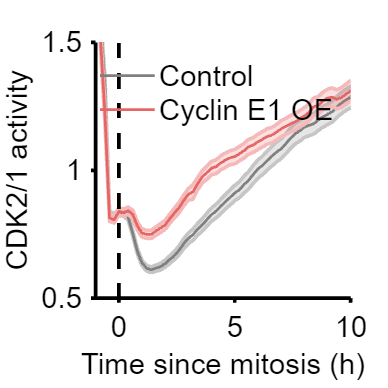


ylabel({'CDK2/1 activity'});xlabel('Time since mitosis (h)');
legend('Control','Cyclin E1 OE','box','off','Location','north','fontsize',16);
set(gca,'linewidth',2,'fontsize',16)
xlim([-1 10]); 
ylim([.5 1.5]);
vline([0],'k--')

% print_pdf(['fig_3Bleft.pdf'])


3B right

conds=[11 13];
colors = [.5 .5 .5;.9 .4 .4;.1 .4 1; .8 .2 .6;.9 .4 0;1 .6 0; 1 .3 .2; 1 .647 .671; .855 .384 .49; .647 .22 .376; .271 .035 .125; .525 .075 .788; .075 .322 .702];
POI_align = 3;
ally = [];
groups = [];
timeGate = [6 8];

for i=1:length(conds)
    c = conds(i);
    data = S(c);
    inds = ~isnan(data.POI(:,POI_align)) &  ...
         data.POI_realtime(:,1) <= timeGate(2) & data.POI_realtime(:,1) >= timeGate(1) & data.apcExpressGate & data.goodCdk;
sum(inds)
    yvals = (data.POI_realtime(inds,3) - data.POI_realtime(inds,1));
    yvals = yvals(yvals < 2000 & yvals >= 0);
    ally = [ally; yvals];
    groups = [groups; repmat(i,size(yvals))];
    meang1(i) = mean(yvals);
    length(yvals);
    cols(i,1) = ({colors(i,:)}');
    groupcol = repmat([colors([1:i],:)],1,1);
 

end

ans = 394

ans = 433

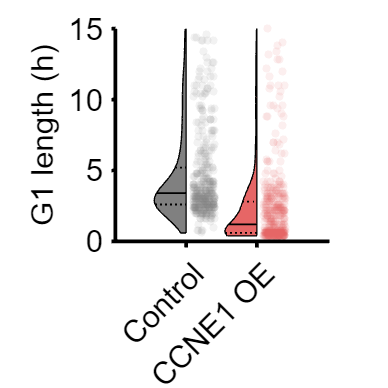


figure('Units', 'Inches', 'Position', [0, 0, 4, 4])
h = violinPlot((ally),'groups',groups, 'showMM',6,'histOpt',1,'divFactor',.5,'histOri','left','widthDiv',[2 1],'color','black');

set(h{1},{'FaceColor'},cols)
hold on
jit = 0.3*rand(size(groups)) + .1;
scatter(groups+jit, (ally), 20,groupcol(groups,:),'filled','MarkerFaceAlpha',.1);
ylabel([ 'G1 length (h)'])


xticklabels({'Control','CCNE1 OE'})
ylim([0 15])
 xtickangle(45)
axis square
set(gca,'fontsize',17,'linewidth',2)

    p=mediantest(ally(groups==1),ally(groups==2))

p = 9.0541e-37

% print_pdf(['fig_3Bright.pdf'])

3C

conds=[11 13];
colors = [.5 .5 .5;.9 .4 .4;.8 .2 .6;.941 .447 .282;1 .831 0;.333 .302 .541; 1 .831 0;  .855 .384 .49; .647 .22 .376; .271 .035 .125; .525 .075 .788; .075 .322 .702];

clear cols;
POI_align = 3;
ally = [];
groups = [];
timeGate = [6 8];

for i=1:length(conds)
    c = conds(i);
    data = S(c);
    inds = ~isnan(data.POI(:,POI_align)) & ~isnan(data.POI(:,2))& ...
         data.POI_realtime(:,1) <= timeGate(2) & data.POI_realtime(:,1) >= timeGate(1) & data.apcExpressGate & data.goodCdk;
sum(inds)
    yvals = (data.POI_realtime(inds,3) - data.POI_realtime(inds,2));
  
    ally = [ally; yvals];
    groups = [groups; repmat(i,size(yvals))];
    meang1(i) = mean(yvals);
    length(yvals);
    cols(i,1) = ({colors(i,:)}');
    groupcol = repmat([colors([1:i],:)],1,1);
 

end

ans = 383

ans = 402

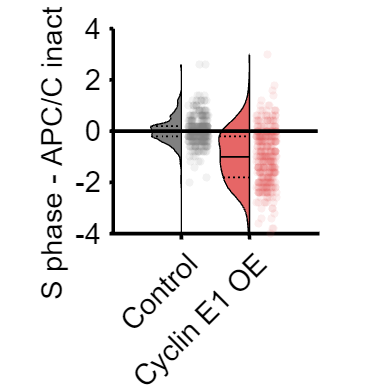


figure('Units', 'Inches', 'Position', [0, 0,5 5])
h = violinPlot((ally),'groups',groups, 'showMM',6,'histOpt',1,'divFactor',1,'histOri','left','widthDiv',[2 1],'color','black');

set(h{1},{'FaceColor'},cols)
hold on
jit = 0.3*rand(size(groups)) + .1;
scatter(groups+jit, (ally), 20,groupcol(groups,:),'filled','MarkerFaceAlpha',.1);
ylabel([ 'S phase - APC/C inact (h)'])

set(gca,'linewidth',2,'fontsize',16)
xticklabels({'Control','Cyclin E1 OE'})
ylim([-4 4])
hline (0,'k')
 xtickangle(45)
axis square


  p=mediantest(ally(groups==1),ally(groups==2))

p = 9.2976e-32


% print_pdf(['fig_3c.pdf'])

3E

conds=[11 13];
timeGate = [6 8];
colors = [.5 .5 .5;.9 .4 .4;.1 .4 1; .8 .2 .6;.9 .4 0;1 .6 0; 1 .3 .2; 1 .647 .671; .855 .384 .49; .647 .22 .376; .271 .035 .125; .525 .075 .788; .075 .322 .702];
figure('unit','inches','position',[0 0 4 4])
hold on
axis square;
POI_align = 3;
for i=1:length(conds)
    c = conds(i);
    data = S(c);
    inds = ~isnan(S(conds(i)).POI(:,POI_align)) &  ...
        S(conds(i)).POI_realtime(:,1) <= timeGate(2) & S(conds(i)).POI_realtime(:,1) >= timeGate(1)&...
        S(conds(i)).apcExpressGate & S(conds(i)).goodCdk;
sum(inds)
    ydata = data.cdk(inds,:);
    POI = data.POI(inds,POI_align) ;
    
    [frames, medSig, semCRL] =get_mean_trace(ydata,POI,1);
    shadedErrorBar((frames)/framesPerHr,medSig,2*semCRL,'lineProps',{'Color',colors(i,:),'LineWidth',1.5});
end

ans = 394

ans = 433

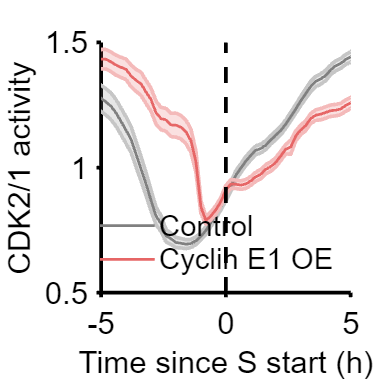

set(gca,'linewidth',2,'fontsize',17)
ylabel({'CDK2/1 activity'});xlabel('Time since S start (h)');
legend('Control','Cyclin E1 OE','box','off','Location','southeast','fontsize',16);

xlim([-5 5]); 
ylim([.5 1.5]);
vline([0],'k--')

% print_pdf(['fig_3E.pdf'])